# Segundo Examen Parcial

# Otoño 2022

Sube tu archivo resultado a Canvas $\to$ Examen Parcial 3 antes de las 9:55 horas. 

**Aseguráte que tus resultados se despliegan en el archivo que subas.**

Al final del script debes incluir las funciones usadas para resolver las preguntas.

Cada pregunta vale 5 puntos.

Si no usas la función indicada se restan 2 puntos en la respuesta. Si no usas el método indicado la respuesta no cuenta.

Los exámenes son trabajos individuales. Está estrictamente prohibido dar o recibir ayuda de cualquier persona. 

**Recuerda salvar frecuentemente tu archivo.**

Puede ser conveniente limpiar periódicamente el espacio de trabajo (comando clear).

En el caso extremo de gráficas que aparecen mal, puedes salir y volver a entrar a la sesión.

## 1. Ecuación diferencial ordinaria de primer orden

Usando el método RK4, resuelve el siguiente problema de valor inicial en el intervalo de t=0 a t=2, donde y(0)=1. Grafica la solución $y\left(t\right)$.


$$\frac{\mathrm{d}}{\mathrm{d}t}y=yt^2 -1\ldotp 1y$$


%Valores iniciales
t0=0; tf=2; y0=1; h=0.1;

f=@(t,y)y*t^2 -1.1*y;

[t1,y1]=RK4(f,t0,tf,y0,h)

t1 =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000


y1 =     1.0000    0.8961    0.8047    0.7254    0.6579    0.6015    0.5554    0.5191    0.4920    0.4738    0.4646    0.4647    0.4752    0.4977    0.5351    0.5916    0.6739    0.7927    0.9646    1.2169    1.5946


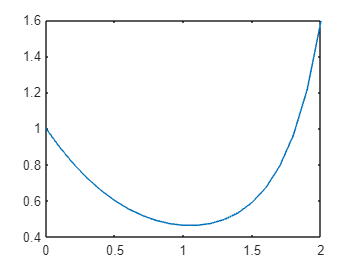


plot(t1,y1)
hold off;

## 2. Sistema de dos ecuaciones diferenciales ordinarias de primer orden - Métodos de paso variable

Usando RKF45, resuelve el siguiente sistema en el rango de t=0 a t=0.4, con y(0)=2 y z(0)=4. Grafica la solución $y\left(t\right)\;$y $z\left(t\right)$.


$$\frac{\mathrm{d}}{\mathrm{d}t}y=-2y+5e^{-t}$$



$$\frac{\mathrm{d}}{\mathrm{d}t}z=-\frac{yz^2 }{2}$$


Usa h=0.1 e imprime el número total de puntos calculados por este método de paso variable.

%Valores iniciales
t0=0;tf=0.4; y0=[2;4];
f=@(t,y) [-2*y(1)+5*exp(-t);-(y(1)*y(2)^2)/2];
h=0.1;

[t2,y2]=odeRKF45(f,y0,t0,tf,h,10^(-6),1000)

t2 =          0    0.0351    0.0701    0.1095    0.1536    0.2030    0.2589    0.3223    0.4000


y2 =     2.0000    2.0309    2.0540    2.0714    2.0816    2.0825    2.0720    2.0478    2.0036
    4.0000    3.5039    3.1139    2.7640    2.4538    2.1784    1.9339    1.7168    1.5124



%Número total de puntos calculados
length(t2)

ans = 9

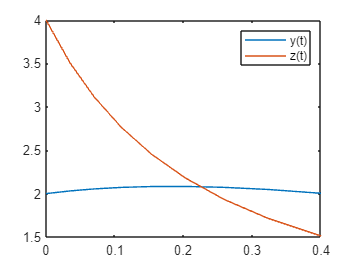


plot(t2,y2)
legend('y(t)','z(t)')
hold off

## 3. Ecuación diferencial ordinaria de segundo orden - Métodos de  múltiples pasos

Usando el método ABM4o, igual al ABM4 pero que solo guarda los últimos cuatro valores de la función, resuelve el siguiente problema de t=0 a t=5.


$$\frac{{\mathrm{d}}^2 }{\mathrm{d}t^2 }y+0\ldotp 6\;\frac{\mathrm{d}}{\mathrm{d}t}y+8y=0$$


donde y(0)=4 y y'(0)=0. Grafica la solución $y\left(t\right)$.

t0=0; tf=5;
y0=[4;0]; h=0.1;

f=@(t,y)[y(2); -(0.6*y(2)+8*y(1))];

[t3,y3]=ABM4o(f,y0,t0,tf,h/3)

t3 =          0    0.0333    0.0667    0.1000    0.1333    0.1667    0.2000    0.2333    0.2667    0.3000    0.3333    0.3667    0.4000    0.4333    0.4667    0.5000    0.5333    0.5667    0.6000    0.6333    0.6667    0.7000    0.7333    0.7667    0.8000    0.8333    0.8667    0.9000    0.9333    0.9667    1.0000    1.0333    1.0667    1.1000    1.1333    1.1667    1.2000    1.2333    1.2667    1.3000    1.3333    1.3667    1.4000    1.4333    1.4667    1.5000    1.5333    1.5667    1.6000    1.6333


y3 =     4.0000    3.9824    3.9300    3.8442    3.7262    3.5779    3.4009    3.1976    2.9702    2.7212    2.4532    2.1689    1.8711    1.5628    1.2469    0.9263    0.6038    0.2825   -0.0350   -0.3459   -0.6476   -0.9376   -1.2137   -1.4736   -1.7154   -1.9373   -2.1378   -2.3155   -2.4693   -2.5984   -2.7021   -2.7799   -2.8318   -2.8577   -2.8580   -2.8332   -2.7839   -2.7111   -2.6159   -2.4996   -2.3637   -2.2096   -2.0391   -1.8541   -1.6565   -1.4482   -1.2312   -1.0078   -0.7799   -0.5497
         0   -1.0545   -2.0789   -3.0646   -4.0040   -4.8895   -5.7144   -6.4728   -7.1593   -7.7692   -8.2987   -8.7447   -9.1050   -9.3781   -9.5633   -9.6607   -9.6713   -9.5966   -9.4390   -9.2015   -8.8878   -8.5021   -8.0493   -7.5347   -6.9640   -6.3434   -5.6792   -4.9783   -4.2475   -3.4938   -2.7243   -1.9461   -1.1661   -0.3914    0.3714    1.1159    1.8358    2.5253    3.1790    3.7917    4.3590    4.8767    5.3413    5.7497    6.0994    6.3886    6.6159    6.7805    6.8822    

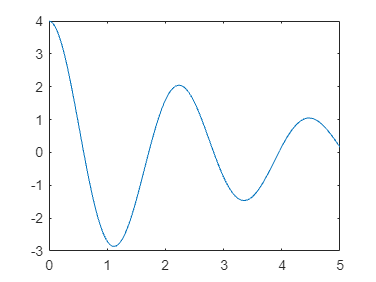


plot(t3,y3(1,:))
hold off

## 4. Problema con valores en la frontera

Grafica la solución $y\left(t\right)\;$de $7\frac{{\mathrm{d}}^2 }{\mathrm{d}t^2 }y-2\frac{\mathrm{d}}{\mathrm{d}t}y-y+t=0$ con las condiciones de frontera $y\left(0\right)=5$ y$y\left(20\right)=8$.

t0=0; tf=20; y0=5; y20=8;

h=0.5; target=1;
f=@(t,y)[y(2);(2*y(2)+y(1)-t)/7];
g=@(z)shooting(f,h,t0,tf,y0,z,target)-y20;

%Esto para más o menos comprobar que sec va a converger
PrimerShoot=shooting(f,h,t0,tf,y0,6,target)

PrimerShoot = 4.7550e+05

SegundoShoot=shooting(f,h,t0,tf,y0,7,target)

SegundoShoot = 5.4514e+05


z1=sec(g,10,20)
y0=[y0;z1];
[t1,y1]=RK4(f,t0,tf,y0,h)

t1 =          0    0.5000    1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    4.0000    4.5000    5.0000    5.5000    6.0000    6.5000    7.0000    7.5000    8.0000    8.5000    9.0000    9.5000   10.0000   10.5000   11.0000   11.5000   12.0000   12.5000   13.0000   13.5000   14.0000   14.5000   15.0000   15.5000   16.0000   16.5000   17.0000   17.5000   18.0000   18.5000   19.0000   19.5000   20.0000


y1 =     5.0000    4.6429    4.3907    4.2306    4.1512    4.1427    4.1964    4.3047    4.4608    4.6588    4.8936    5.1605    5.4557    5.7754    6.1165    6.4762    6.8520    7.2415    7.6426    8.0532    8.4714    8.8952    9.3225    9.7511   10.1783   10.6013   11.0164   11.4190   11.8035   12.1628   12.4874   12.7654   12.9811   13.1138   13.1368   13.0147   12.7015   12.1364   11.2397    9.9068    8.0000
   -0.8286   -0.6047   -0.4083   -0.2360   -0.0847    0.0479    0.1643    0.2664    0.3560    0.4344    0.5032    0.5633    0.6159    0.6618    0.7017    0.7363    0.7660    0.7913    0.8124    0.8295    0.8427    0.8518    0.8567    0.8568    0.8513    0.8393    0.8193    0.7893    0.7465    0.6874    0.6072    0.4996    0.3561    0.1659   -0.0857   -0.4178   -0.8554   -1.4316   -2.1900   -3.1876   -4.4996


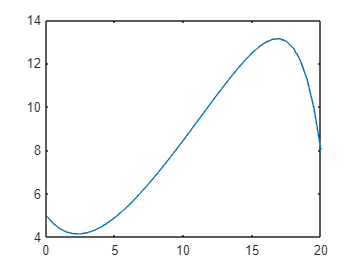


plot(t1,y1(1,:))
hold off

### Inserta aquí las funciones usadas

#### RK4

% function [t,y]=RK4(f,t0,tf,y0,h)
%     t=t0:h:tf;
%     n=length(t);
%     y=zeros(length(y0),n);    
%     y(:,1)=y0;
%     for i=1:n-1
%         k1=f(t(i),y(:,i));
%         k2=f(t(i)+h/2,y(:,i)+0.5*k1*h);
%         k3=f(t(i)+0.5*h,y(:,i)+0.5*k2*h);
%         k4=f(t(i)+h,y(:,i)+k3*h);
%         y(:,i+1)=y(:,i)+(k1+2*k2+2*k3+k4)*h/6;
%     end
% end

#### RKF45

% function [t,y] = odeRKF45(f,y0,t0,tf,h,relTol,max)
%     i=1;
%     t(i)=t0;
%     y(:,i)=y0;
%     while t(end)<tf && i<max
%         if t(end)+1.1*h >= tf
%             h=tf-t(end);
%         end
%         [z,re] = rkf45step(f,t(end),y(:,end),h);
%         if re <= relTol
%             t(end+1) = t(end)+h;
%             y(:,end+1) = z;
%             i=i+1;
%         end
%         h= 0.9*h*nthroot(relTol/re,5); % nthroot saca la raíz quinta (5)
%     end
% end
% 
% function [z,err]=rkf45step(f,t,w,h)
%     s1=f(t,w);
%     s2=f(t+1/4*h,w+1/4*h*s1);
%     s3=f(t+3/8*h,w+3/32*h*s1+9/32*h*s2);
%     s4=f(t+12/13*h, w+1932/2197*h*s1 -7200/2197*h*s2 + 7296/2197*h*s3);
%     s5=f(t+h,w + 439/216*h*s1 -8*h*s2 +3680/513*h*s3 -845/4104*h*s4);
%     s6=f(t+1/2*h, w-8/27*h*s1+2*h*s2-3544/2565*h*s3 +1859/4104*h*s4 -11/40*h*s5);
% 
%     wp=w;
% 
%     w=wp+h*(25/216*s1 + 1408/2565*s3 + 2197/4104*s4 - 1/5*s5);
%     z=wp+h*(16/135*s1 +6656/12825*s3 + 28561/56430*s4 - 9/50*s5 +2/55*s6);
% 
%     err=norm((z-w)./z, Inf);
% end

#### ABM4

% function [t,y]=ABM4o(f,y0,t0,tf,h)
%     t=t0:h:tf;
%     n=length(t);
%     y=zeros(length(y0) ,n);
%     fv=zeros(length(y0),n);
%     
%     steps=4;
%     [t(1:steps),y(:,1:steps)]=RK4(f,t0,t0+h*(steps-1),y0,h);
%     fv(:,1:steps)=bsxfun(f,t(1:steps),y(:,1:steps)); %agarra un valor de la t, y la primer columna del y y aplica la funcion f.
% 
% for i=4:n-1
%     %predictor-Adams-Bashford
%     y(:,i+1)= y(:,i) + (h/24)*( 55*fv(:,i) - 59*fv(:,i-1) + 37*fv(:,i-2) - 9*fv(:,i-3));
%     fv(:,i+1)=f(t(i+1),y(:,i+1));
%     %corrector
%     y(:,i+1)=y(:,i) + (h/24)*( 9*fv(:,i+1) + 19*fv(:,i) - 5*fv(:,i-1) + fv(:,i-2));
%     fv(:,i+1)=f(t(i+1),y(:,i+1));
% end